# Load data

load('Assignment_Data_SC42145.mat');
G = tf(FWT(1:2,1:2));

## RGA analysis

at 0 rad/s and 0.4 rad/s

% compute RGA
RGA = G.*inv(G)';
RGA_0 = evalfr(RGA, 0);
RGA_04 = evalfr(RGA, 0.4);

% singular value decomposition
[U0,S0,V0] = svd(RGA_0); 
[U04,S04,V04] = svd(RGA_0);

max_sigma_0 = max(diag(S0));
min_sigma_0 = min(diag(S0));
gamma_0 = max_sigma_0/min_sigma_0;

max_sigma_04 = max(diag(S04));
min_sigma_04 = min(diag(S04));
gamma_04 = max_sigma_04/min_sigma_04;

## Poles and zeros

poles = pole(FWT)

poles =   -0.0832 + 3.2936i
  -0.0832 - 3.2936i
  -0.4104 + 0.0000i
  -0.0106 + 0.2022i
  -0.0106 - 0.2022i


zeros_ = tzero(FWT)

zeros_ =   -0.0078 + 1.2358i
  -0.0078 - 1.2358i


## Generalized Plant

% build W matrices
Wp11 = tf([1/1.8, 0.8*pi], [1, 0.8*pi*1e-4]);
Wu22 = tf([5e-3, 7e-4, 5e-5], [1, 14e-4, 1e-6]);

Wp = [Wp11 0; 0 0.2];
Wu = [0.01 0; 0 Wu22];

% build generalized plant
P11=[Wp; zeros(2,2)]; P12=[Wp*G; Wu]; P21=eye(2); P22=G;
P = [P11 P12; P21 P22];


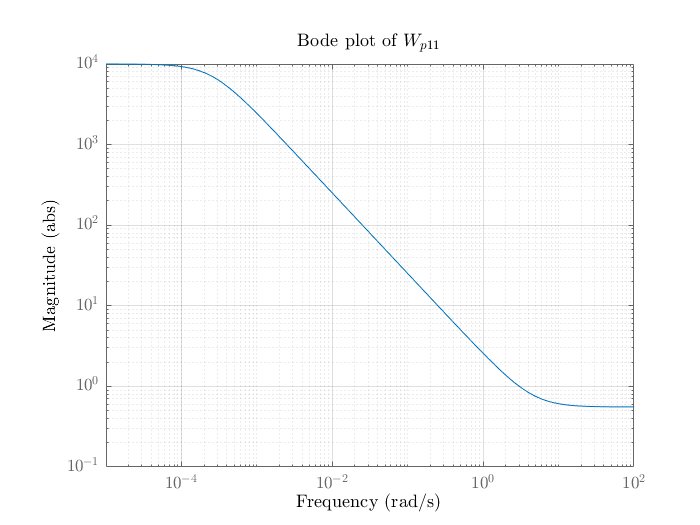

%Make Bode plots
figure()
set(groot,'defaulttextinterpreter','latex');  
set(groot, 'defaultAxesTickLabelInterpreter','latex'); 
bodemag(Wp11)
grid on
setoptions(gcr,'MagUnits','abs', 'MagScale', 'log');
title('Bode plot of $W_{p11}$','interpreter', 'latex')
xlabel('Frequency','interpreter', 'latex')
ylabel('Magnitude','interpreter', 'latex')
set(gcf,'renderer','painters');
saveas(gcf, 'Figures/ch2_mimo_weights_p_filter.eps',  'epsc')

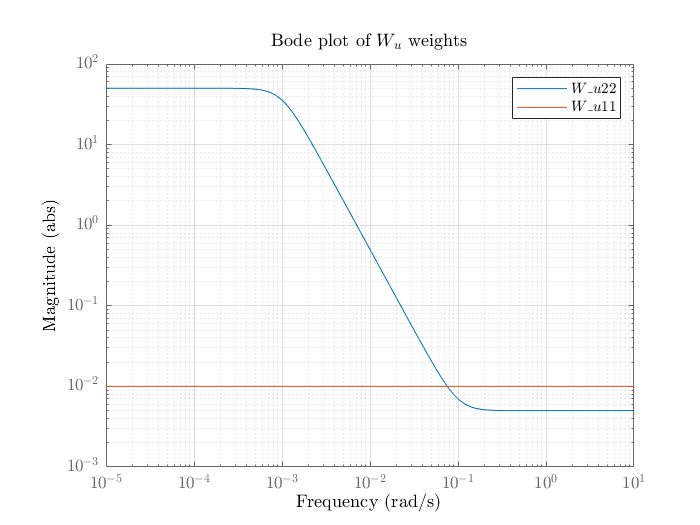


figure()

bodemag(Wu22)
title('Wu22'); grid on
hold on
bodemag(tf([0.01]))
setoptions(gcr,'MagUnits','abs', 'MagScale', 'log');
xlabel('Frequency','interpreter', 'latex')
ylabel('Magnitude','interpreter', 'latex')
title('Bode plot of $W_u$ weights','interpreter', 'latex')
legend("$W_{u22}$", "$W_{u11}$", 'Interpreter','latex')
set(gcf,'renderer','painters');
saveas(gcf, 'Figures/ch2_mimo_weights_u_filter.eps',  'epsc')

## Controller Synthesis

[K, CL, gamma,syn_info] = hinfsyn(P, 2, 2); %2 inputs, 2 outputs
H_inf_norm_CL = gamma

H_inf_norm_CL = 0.7993


pole(K)

ans =  -34.0428 + 0.0000i
   0.0083 + 3.4260i
   0.0083 - 3.4260i
  -0.0832 + 3.2936i
  -0.0832 - 3.2936i
  -0.0832 + 3.2936i
  -0.0832 - 3.2936i
  -0.0671 + 0.2130i
  -0.0671 - 0.2130i
  -0.0572 + 0.0637i


## Closed loop performance

reference tracking of $\omega_r$ and disturbance rejection of V

% define inputnames of K
K.InputName = {'dOmega'; 'z (m)'};
K.OutputName = {'Beta (deg)'; 'tau_e (Nm)'};
dOmega_sum = sumblk('dOmega = r - Omega (rad/s)');

%first connect sum block with K by connecting inputs and outputs
%the new model has inputs [r,Omega,z] and outputs [beta, tau]
ref_tf = connect(dOmega_sum, -K,  {'r';'Omega (rad/s)'; 'z (m)'},{'Beta (deg)';'tau_e (Nm)'});
%these outputs are connected as inputs of the plant
%the inputs of the connected system are the exogenous inputs [r,V]
%we would like to monitor [r,z,Omega,tau,V], so these are the chosen outputs
outputs_ = {'r';'V (m/s)';'Omega (rad/s)'; 'z (m)';'Beta (deg)';'tau_e (Nm)'};
closed_loop = connect(ref_tf, FWT, {'r';'V (m/s)'}, outputs_);
closed_loop = minreal(closed_loop);

22 states removed.


## Nyquist

G2 = FWT(1:2,1:2);
L = tf(-G2*K);
f = eye(2)+L;

figure()
latex_nyquist(f(1,1)*f(2,2)-f(1,2)*f(2,1), "Generalized nyquist");

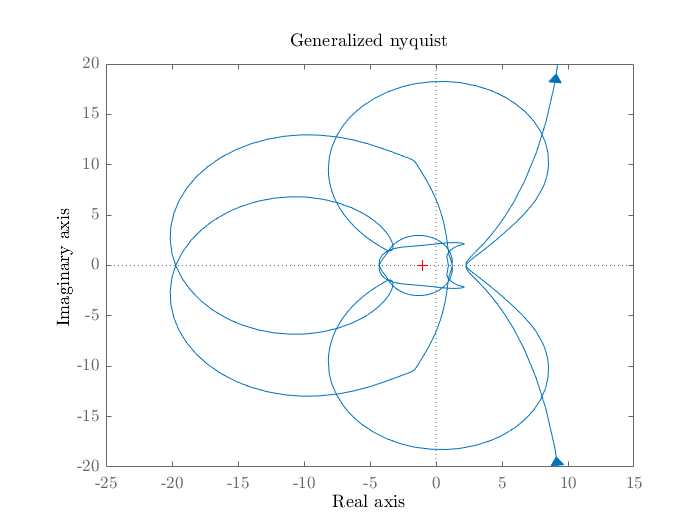

set(gcf,'renderer','painters');
saveas(gcf, 'Figures/ch2_nyquist.eps',  'epsc');
grid off; xlim([-25 15]); ylim([-20 20]);
set(gcf,'renderer','painters');
saveas(gcf, 'Figures/ch2_nyquist_zoom.eps', 'epsc');


% f2 = L
% data = reshape(freqresp(f2,s),[],1);
% plot(real(data),imag(data))

% 
% 
% f = 5*closed_loop(3:4,:)/openloop;
% 
% data = freqresp(f,s);
% 
% sets = [[1,1];[1,2];[2,1];[2,2]];
% lims = [-5,5; -0.005,0.005; -10,10;-5,5];
% 
% for i = 1:4
%     subplot(2,2,i)
%     
%     d1 = reshape(data(sets(i,1),sets(i,2),:),[],1);
%     plot(real(d1),imag(d1))
%     xlim(lims(i,:)); ylim(lims(i,:))
%     xline(0); yline(0);
%     xlabel('Real')
%     ylabel("Imaginary")
% end


## Build plots

clf
figsize = [0,0,6,4 *6]

figsize =      0     0     6    24


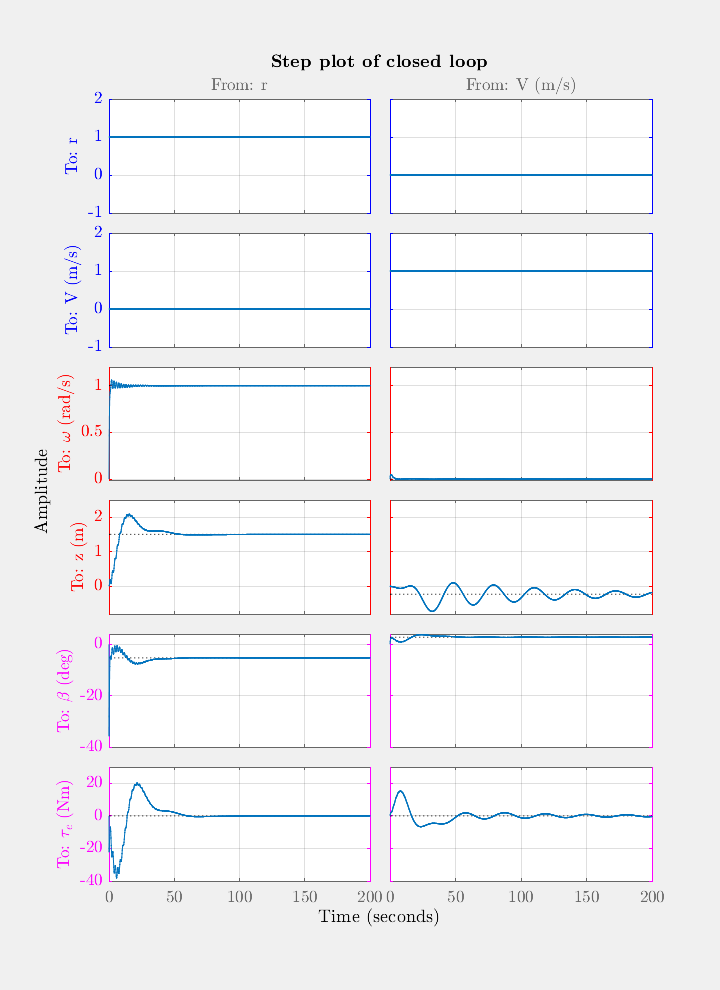

figure('units','inch','position',figsize);


latex_step(closed_loop, " closed loop", 200)
%step(closed_loop)
%[Y_sim, T_sim] = step(closed_loop);
axs= findobj(allchild(gcf), 'flat', 'Type', 'axes');

%exogenous inputs
axs(12).YColor='Blue';
axs(13).YColor='Blue';
axs(7).YColor='Blue';
axs(6).YColor='Blue';

%outputs
axs(11).YColor='Red';
axs(10).YColor='Red';
axs(5).YColor='Red';
axs(4).YColor='Red';

%control inputs
axs(9).YColor='Magenta';
axs(8).YColor='Magenta';
axs(3).YColor='Magenta';
axs(2).YColor='Magenta';

set(gcf,'Visible','on');
set(gcf,'renderer','painters');
saveas(gcf, 'Figures/ch2_mimo_simulation.eps',  'epsc');